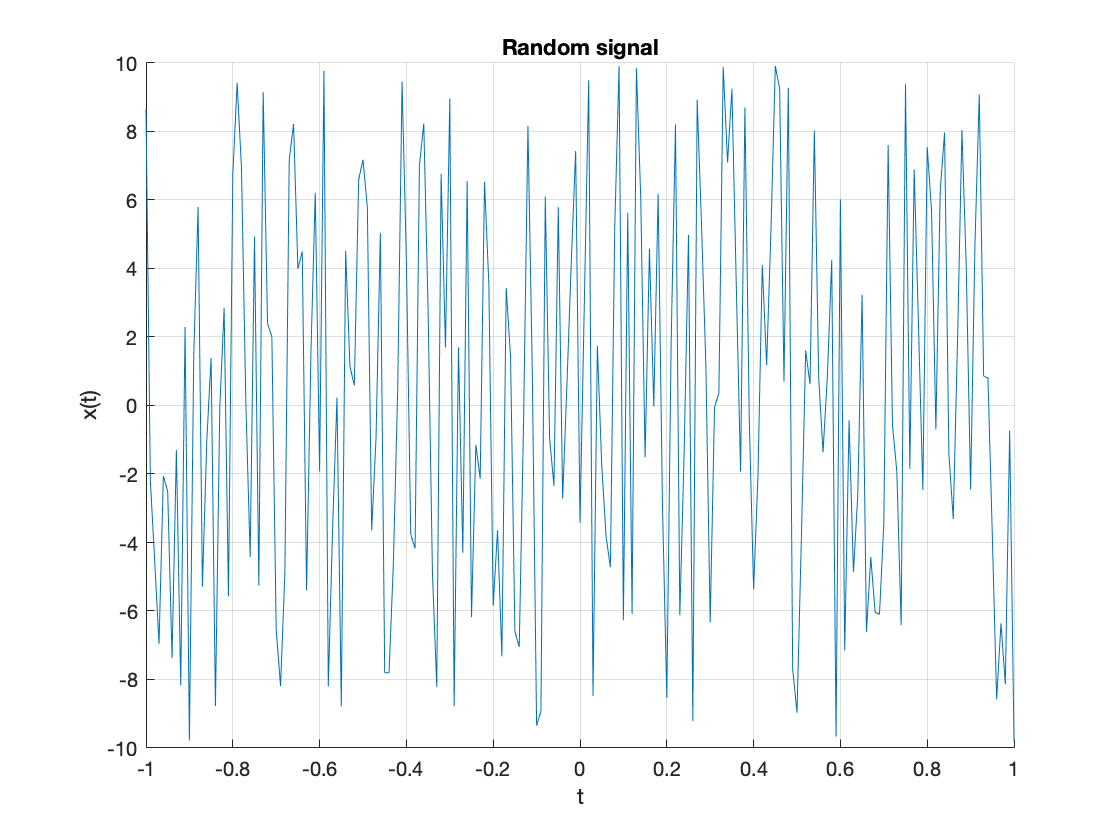

%TASK-2-PART-1-----------------------------------------
count_set = [-1:0.01:1];
x_min     = -10;
x_max     = 10;

figure(1)
original_signal = GenerateRandomSignal(count_set, x_min, x_max);

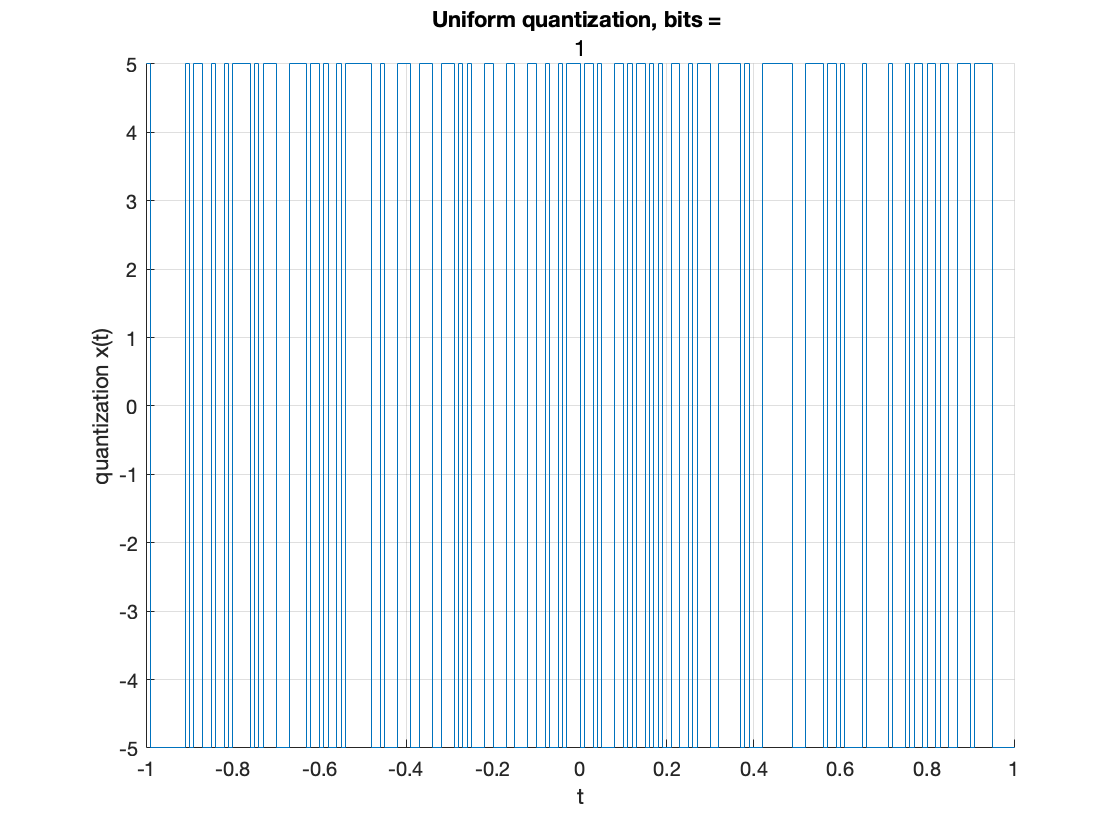

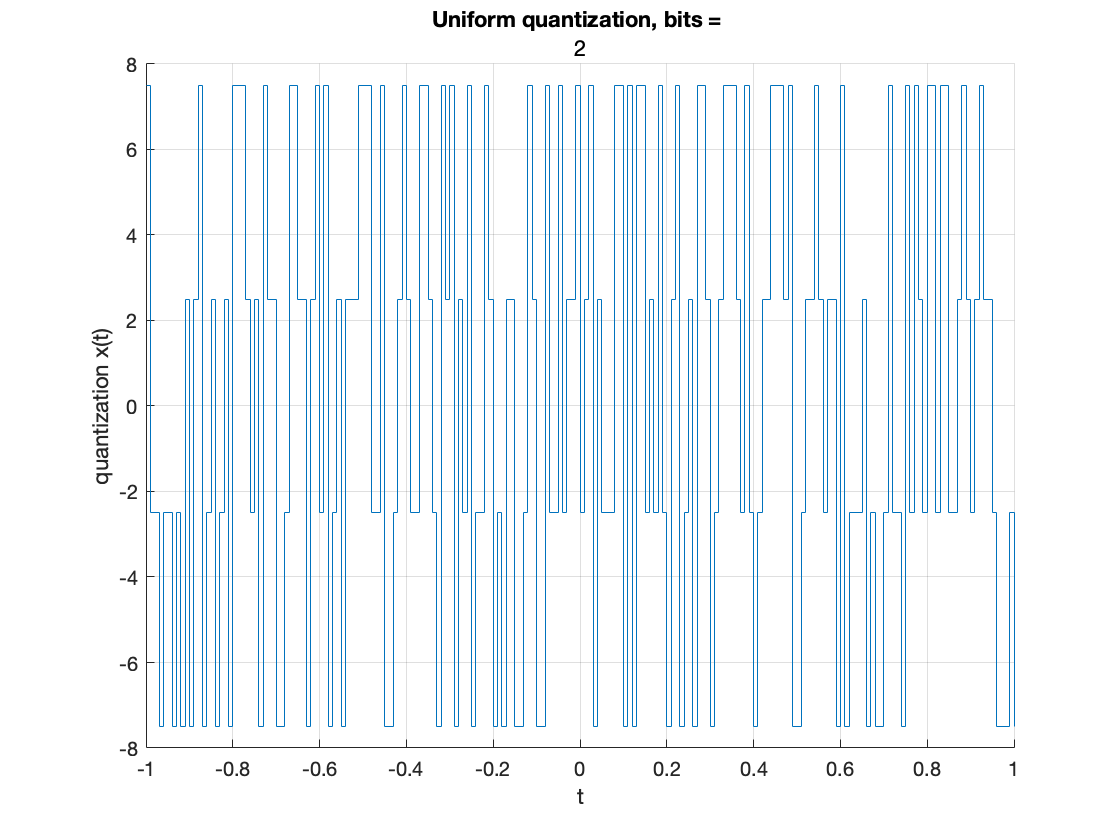

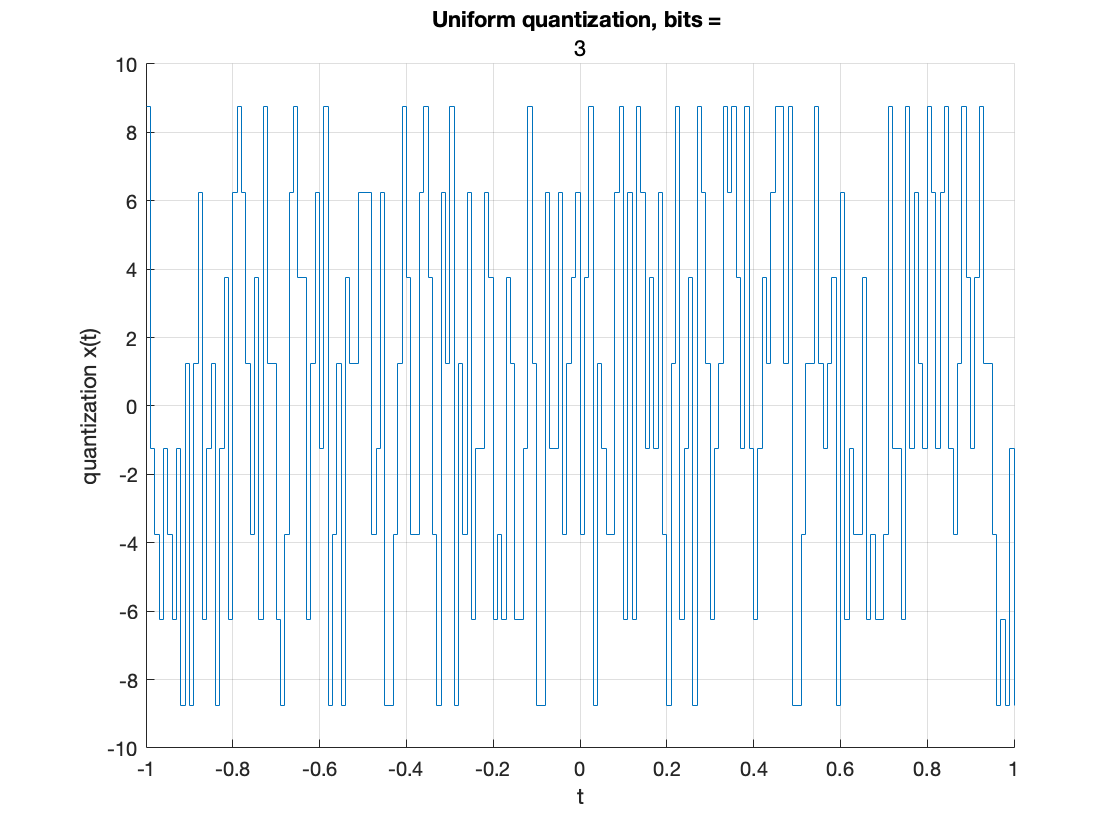

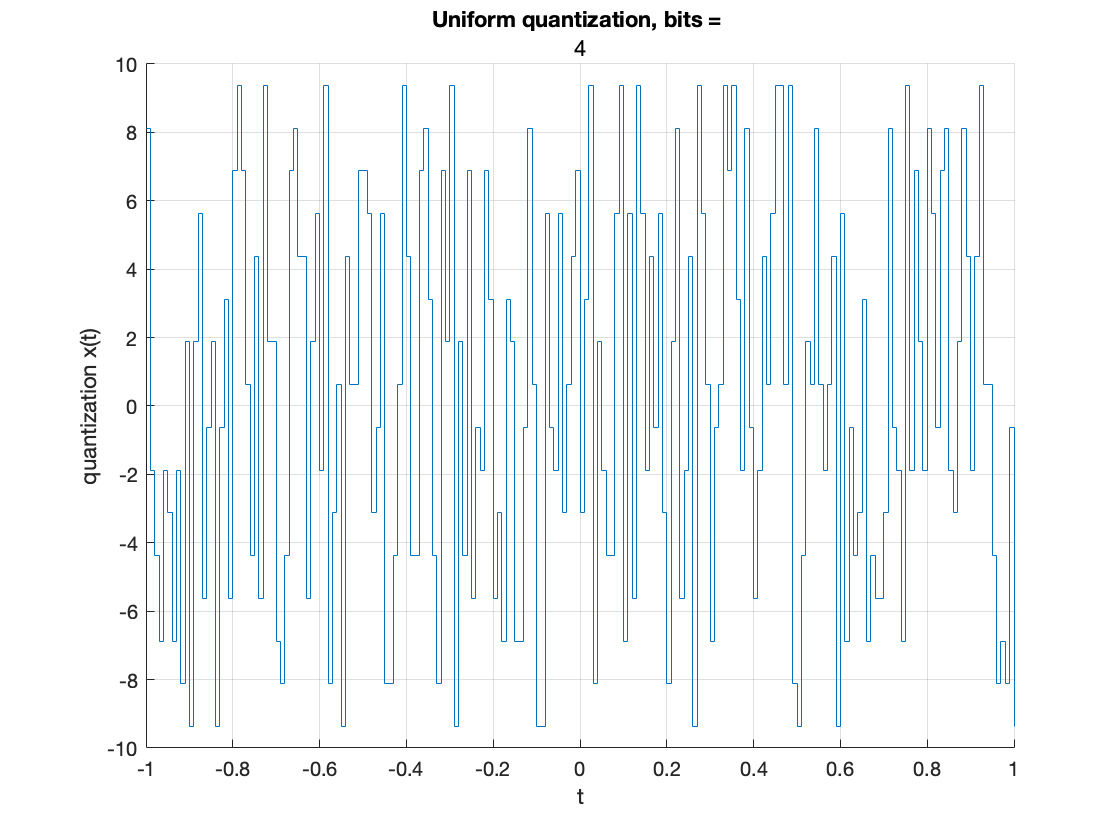

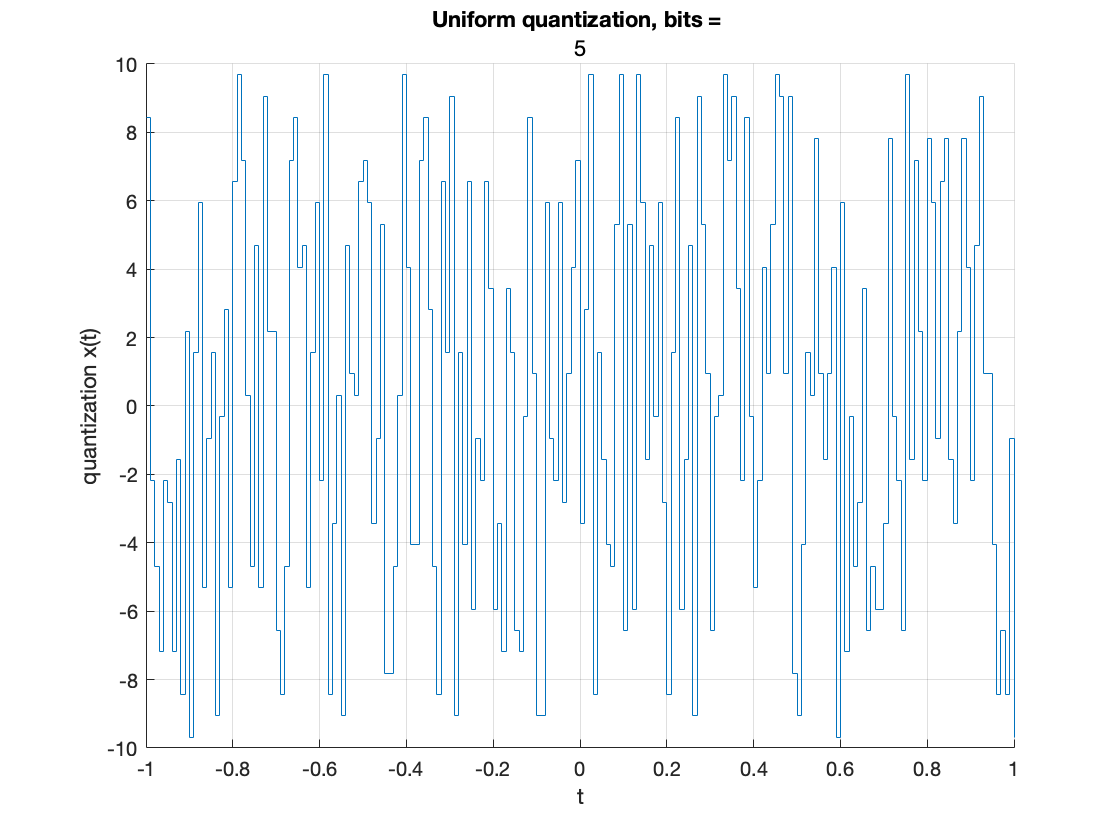

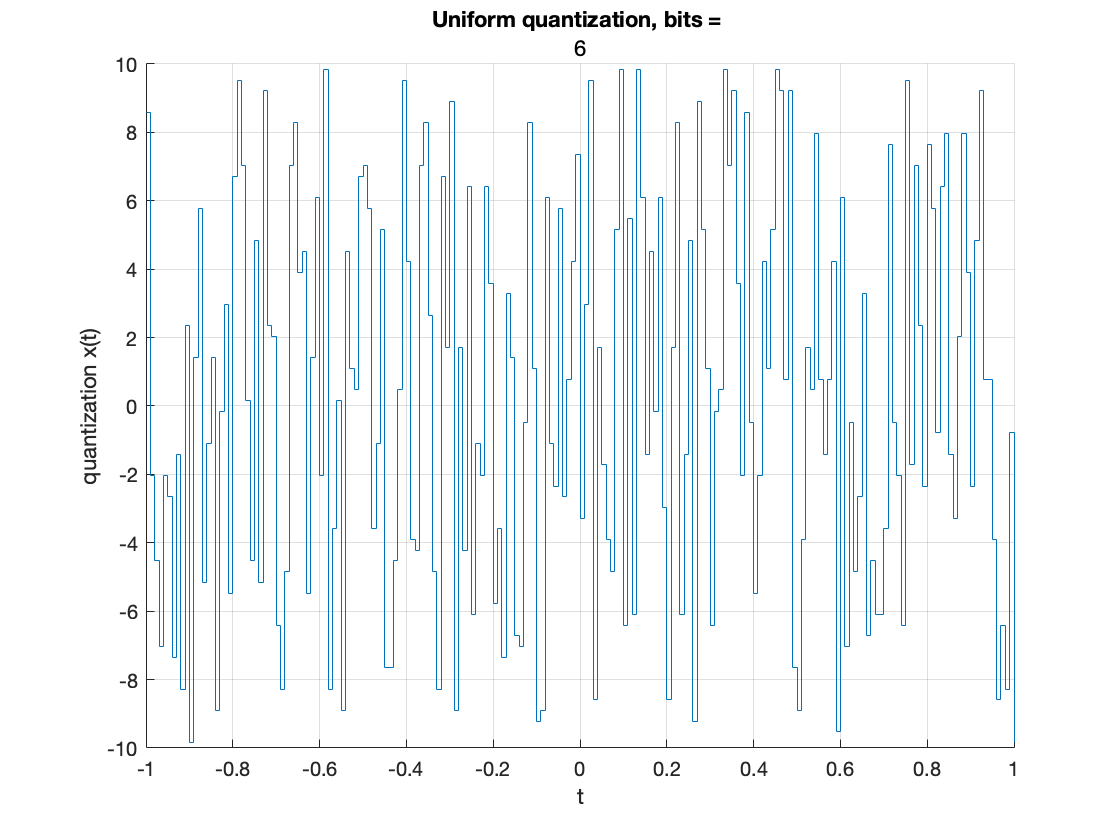

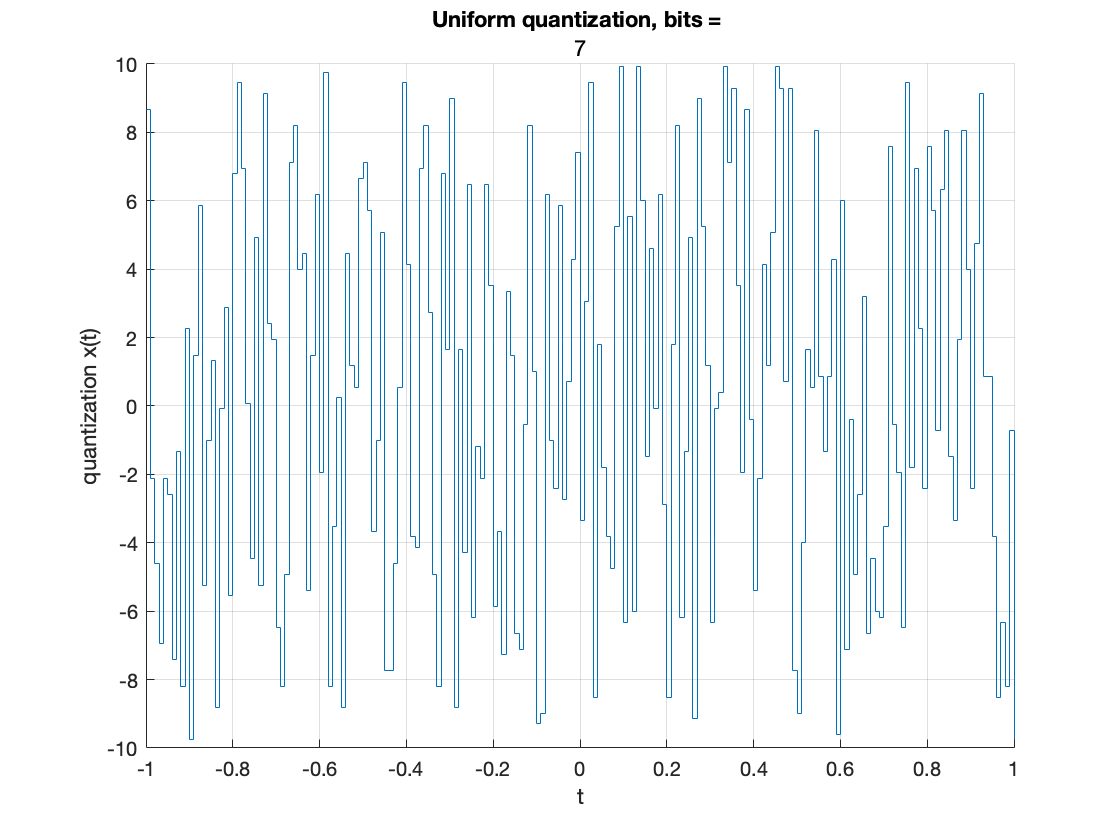

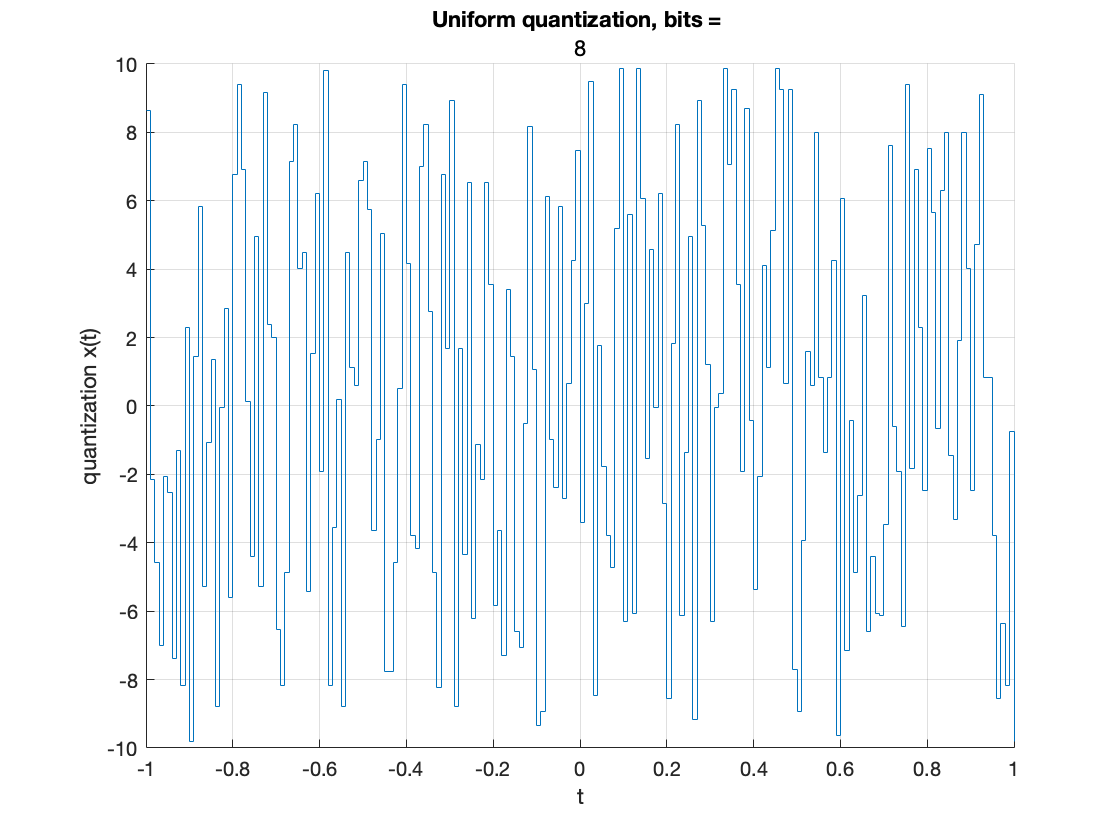



%TASK-2-PART-2-----------------------------------------
quantorization_signal = zeros(8,length(original_signal));
for k = 1:1:8
    figure(k+1)
    quantorization_signal(k,:) = UniformQuantization(original_signal, count_set, k, x_min, x_max);
end

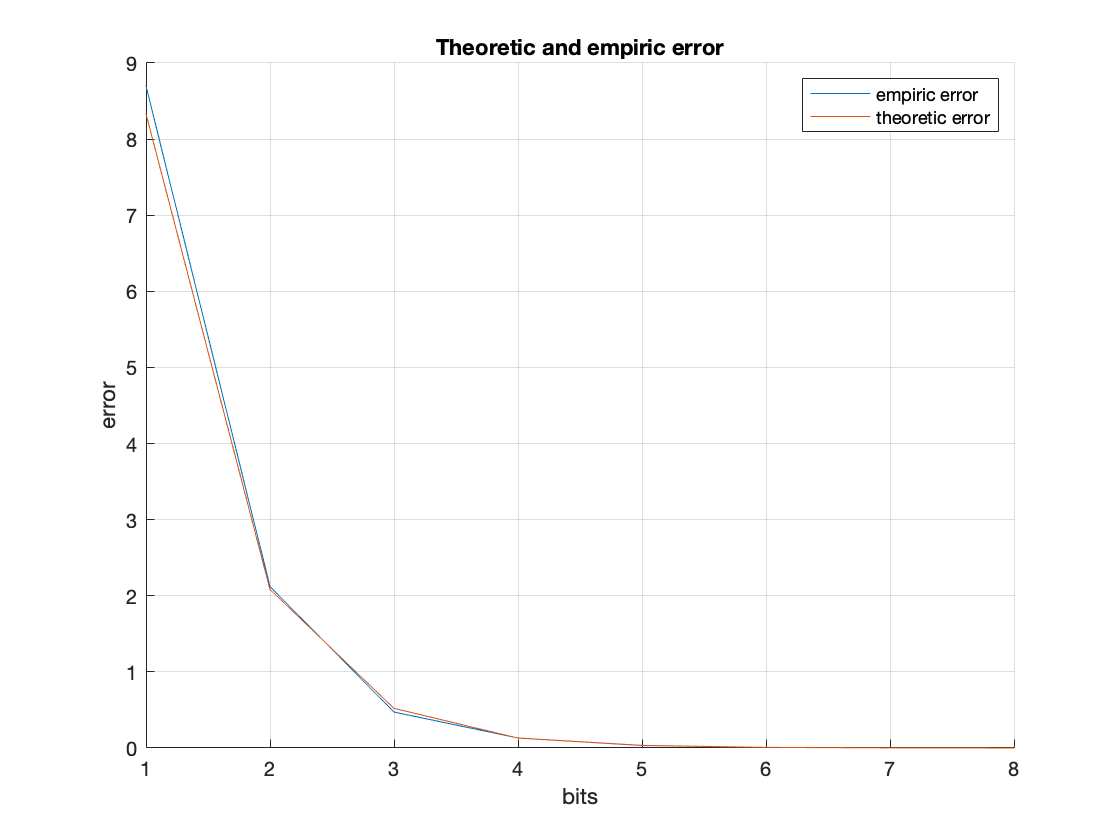

error_empiric =     8.6993    2.1217    0.4724    0.1314    0.0342    0.0075    0.0020    0.0005


error_theoretic =     8.3333    2.0833    0.5208    0.1302    0.0326    0.0081    0.0020    0.0005



%TASK-2-PART-3-----------------------------------------
figure(10)
[error_empiric, error_theoretic] = QuantizationError(original_signal, quantorization_signal, x_min, x_max)

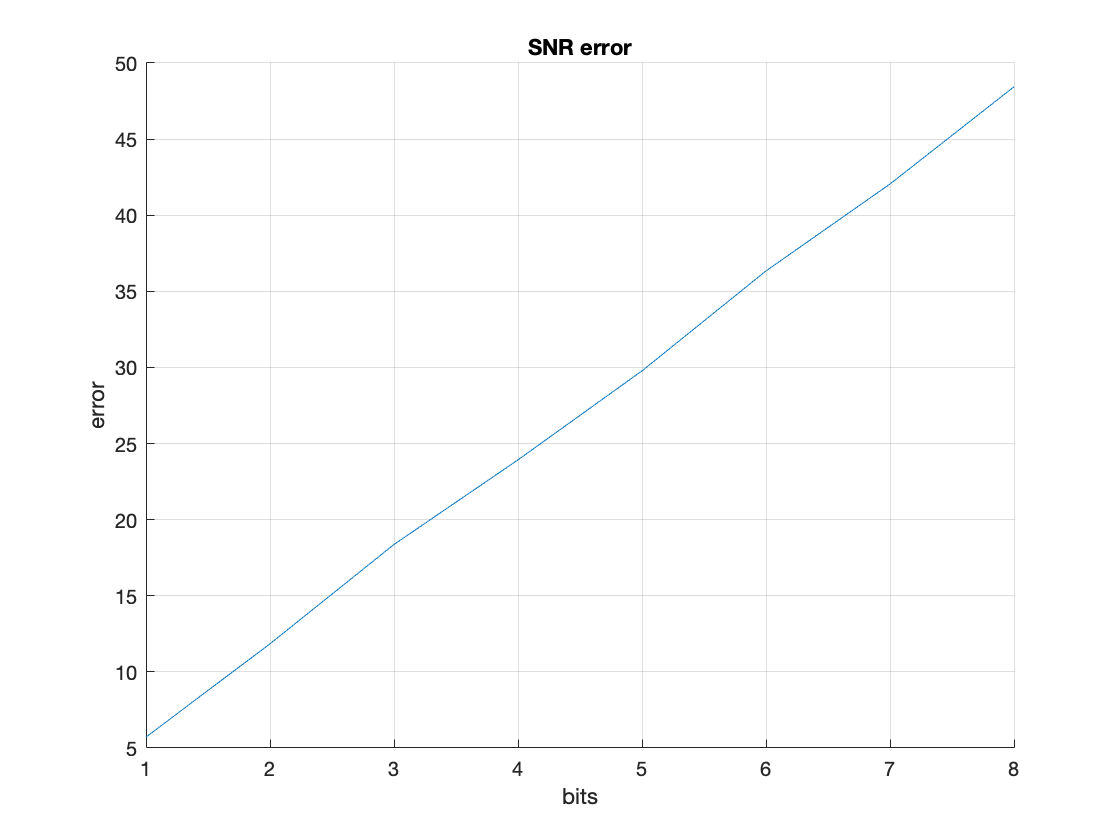

error_SNR =     5.7199   11.8480   18.3719   23.9297   29.7775   36.3409   42.0524   48.4384



%TASK-2-PART-4-----------------------------------------
figure(11)
error_SNR = QuantizationErrorSNR(original_signal, quantorization_signal, x_min, x_max)

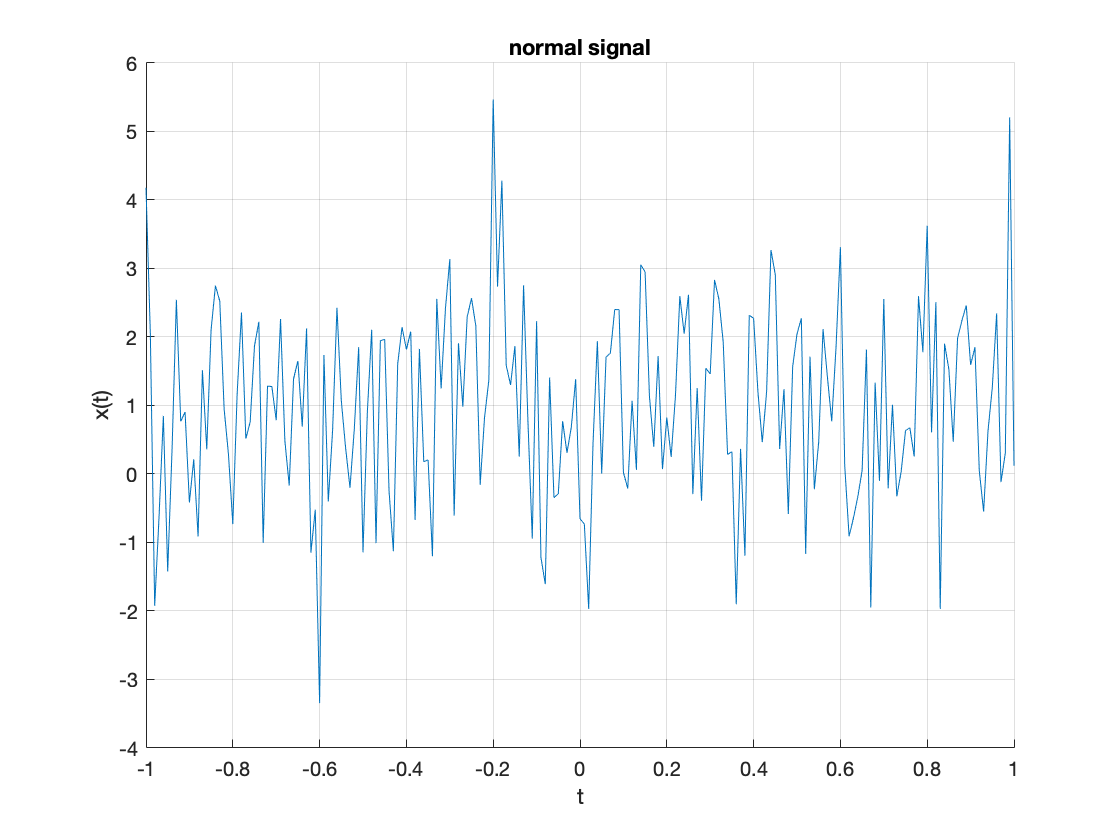


%TASK-2-PART-5-----------------------------------------
m = 1; sigma = 2;
figure(12)
normal_signal = GenerateRandomNormalSignal(m, sigma, count_set);

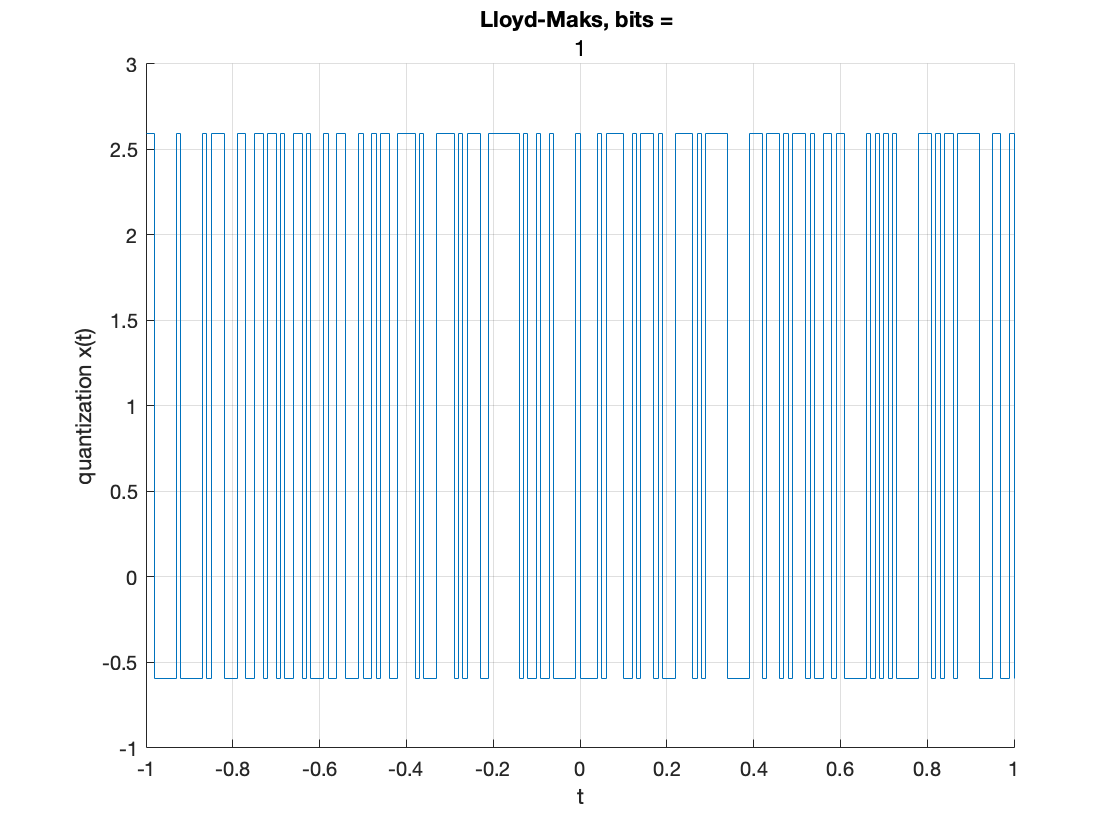


%TASK-2-PART-6-----------------------------------------
% При использовании 1 бита на отсчет (2 уровня):
t1 = [-inf 0 inf];
d1 = [-0.7979 0.7979];
% При использовании 2 бит на отсчет(4 уровня):
t2 = [-inf -0.9816 0 0.9816 inf];
d2 = [-1.5104 -0.4528 0.4528 1.5104];
% При использовании 3 бит на отсчет (8 уровней):
t3 = [-inf -1.7479 -1.05 -0.5005 0 0.5005 1.05 1.7479 inf];
d3 = [-2.1519 -1.3439 -0.756 -0.2451 0.2451 0.756 1.3439 2.1519];
% При использовании 4 бит на отсчет (16 уровней):
t4 = [-inf -2.4008 -1.8435 -1.4371 -1.0993 -0.7995 -0.5224 -0.2582 0 0.2582 0.5224 0.7995 1.0993 1.4371 1.8435 2.4008 inf];
d4 = [-2.7326 -2.069 -1.618 -1.2562 -0.9423 -0.6568 -0.3880 -0.1284 0.1284 0.3880 0.6568 0.9423 1.2562 1.618 2.069 2.7326];

[t1_new,d1_new] = LloidMaksForNormal(t1,d1,m,sigma);
[t2_new,d2_new] = LloidMaksForNormal(t2,d2,m,sigma);
[t3_new,d3_new] = LloidMaksForNormal(t3,d3,m,sigma);
[t4_new,d4_new] = LloidMaksForNormal(t4,d4,m,sigma);

%TASK-2-PART-7-----------------------------------------
quantorization_signal_norm = zeros(4,length(original_signal));

figure(13)
quantorization_signal_norm(1,:) = OptimalLloydMaxQuantizer(normal_signal, t1_new, d1_new, count_set);

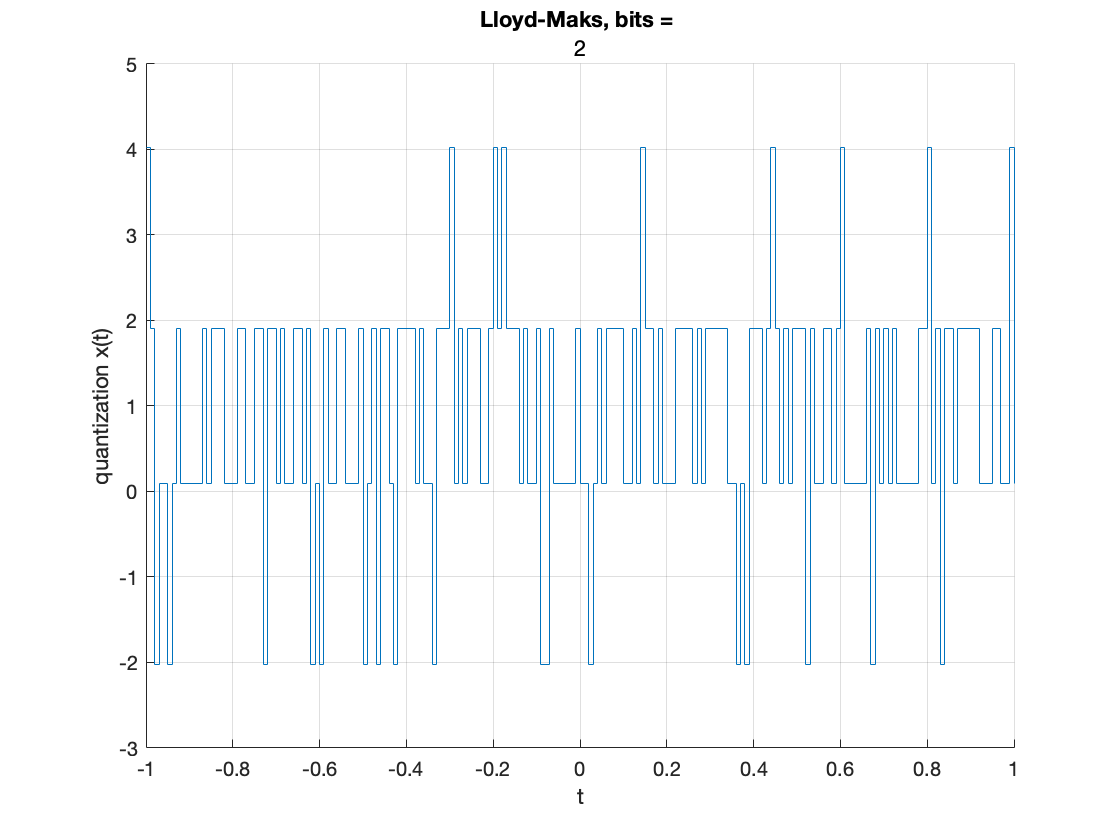


figure(14)
quantorization_signal_norm(2,:) = OptimalLloydMaxQuantizer(normal_signal, t2_new, d2_new, count_set);

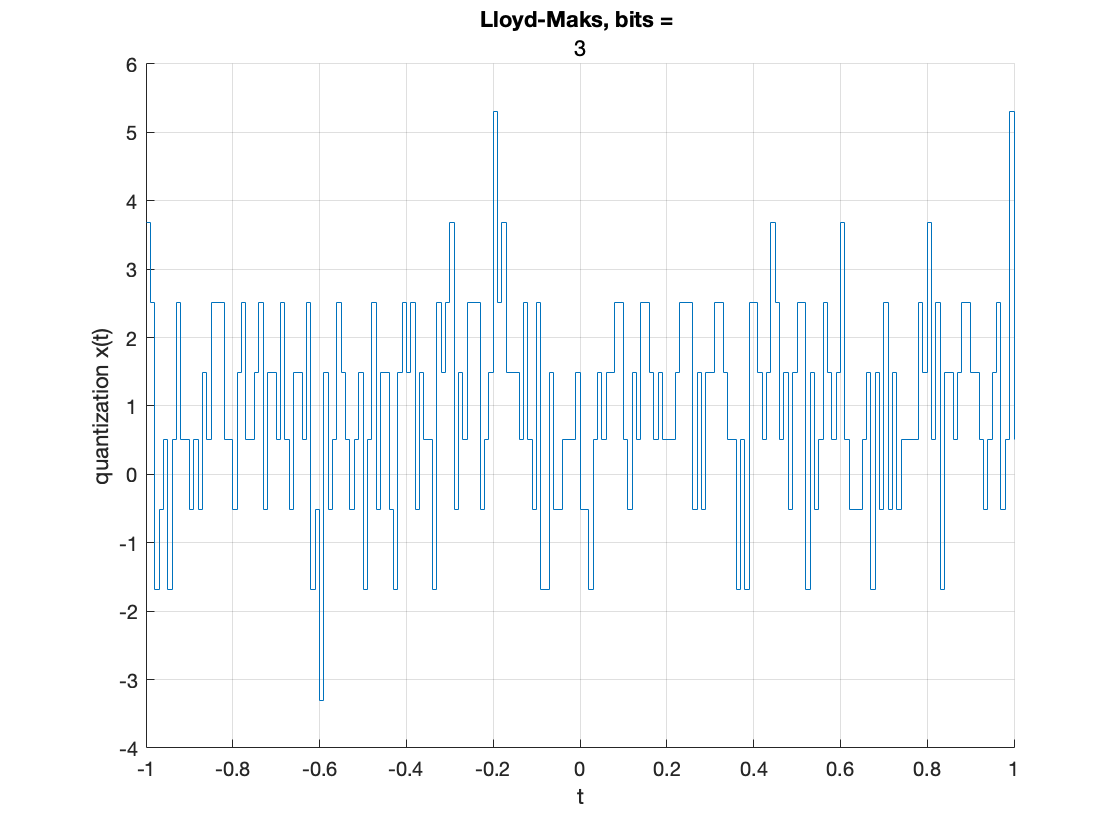


figure(15)
quantorization_signal_norm(3,:) = OptimalLloydMaxQuantizer(normal_signal, t3_new, d3_new, count_set);

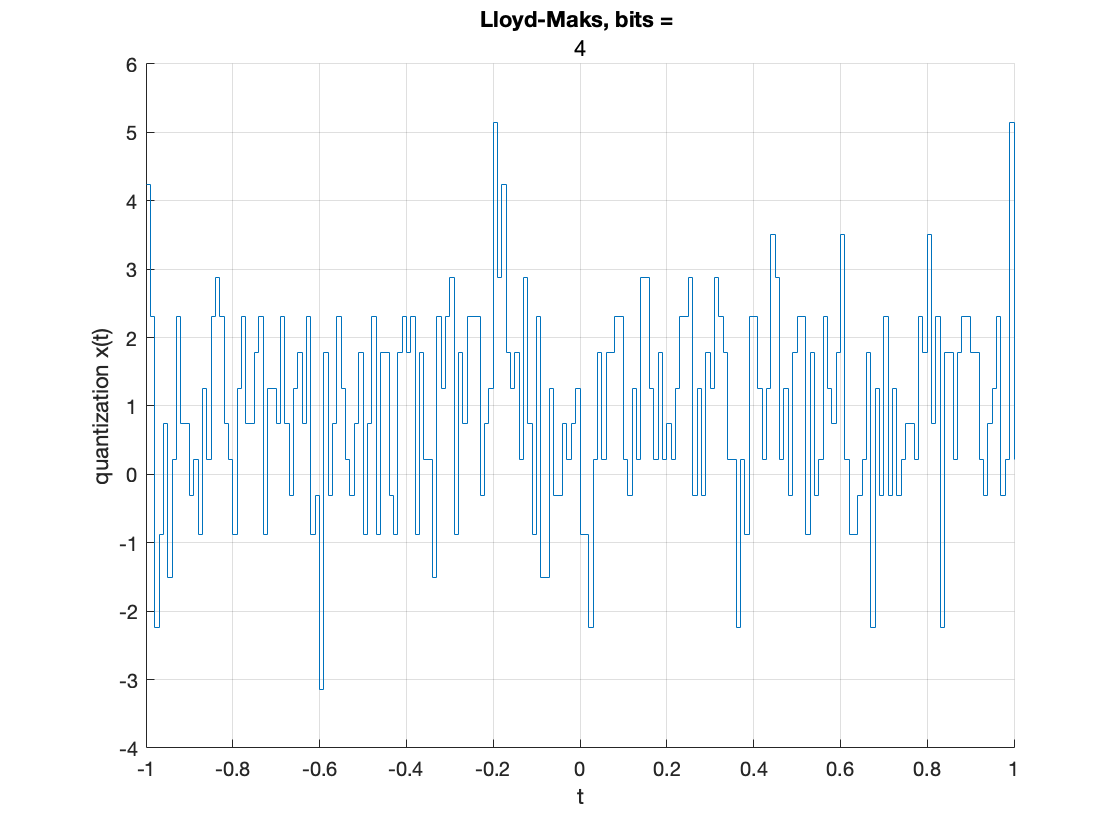


figure(16)
quantorization_signal_norm(4,:) = OptimalLloydMaxQuantizer(normal_signal, t4_new, d4_new, count_set);

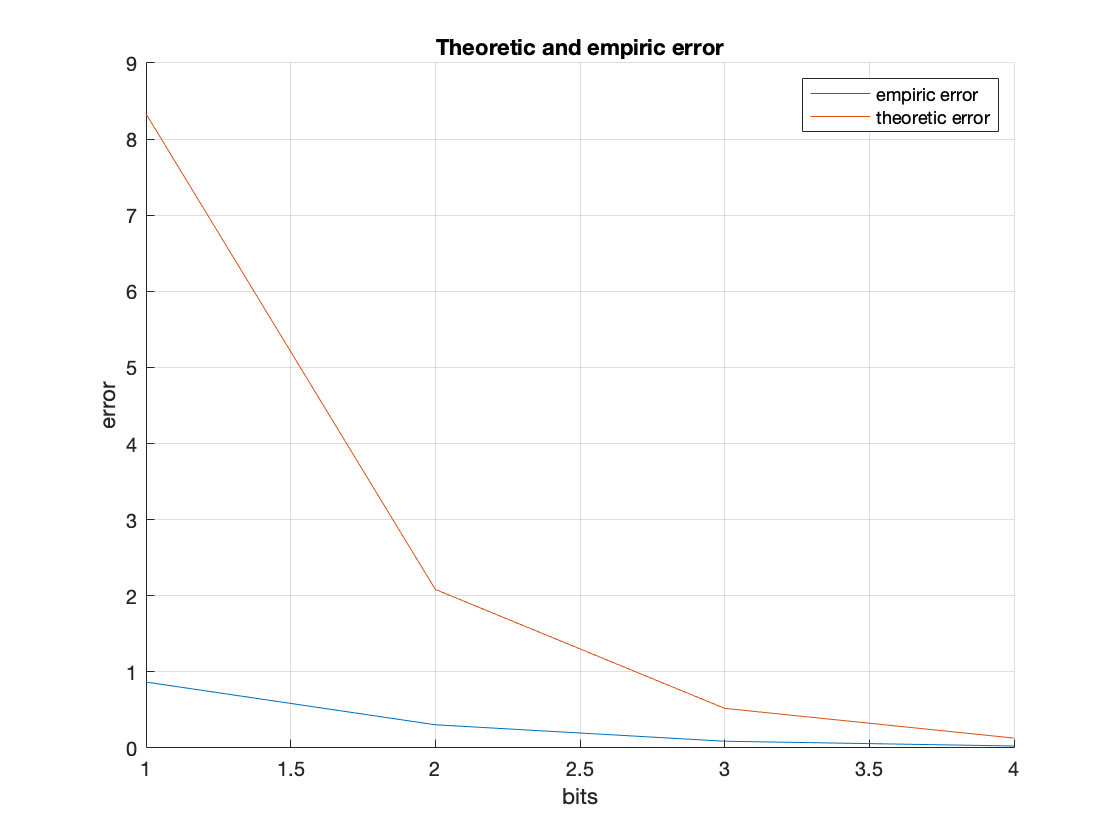

error_empiric_norm =     0.8664    0.3051    0.0890    0.0263


error_theoretic_norm =     8.3333    2.0833    0.5208    0.1302



%TASK-2-PART-8-----------------------------------------
figure(17)
[error_empiric_norm, error_theoretic_norm] = QuantizationError(normal_signal, quantorization_signal_norm, x_min, x_max)

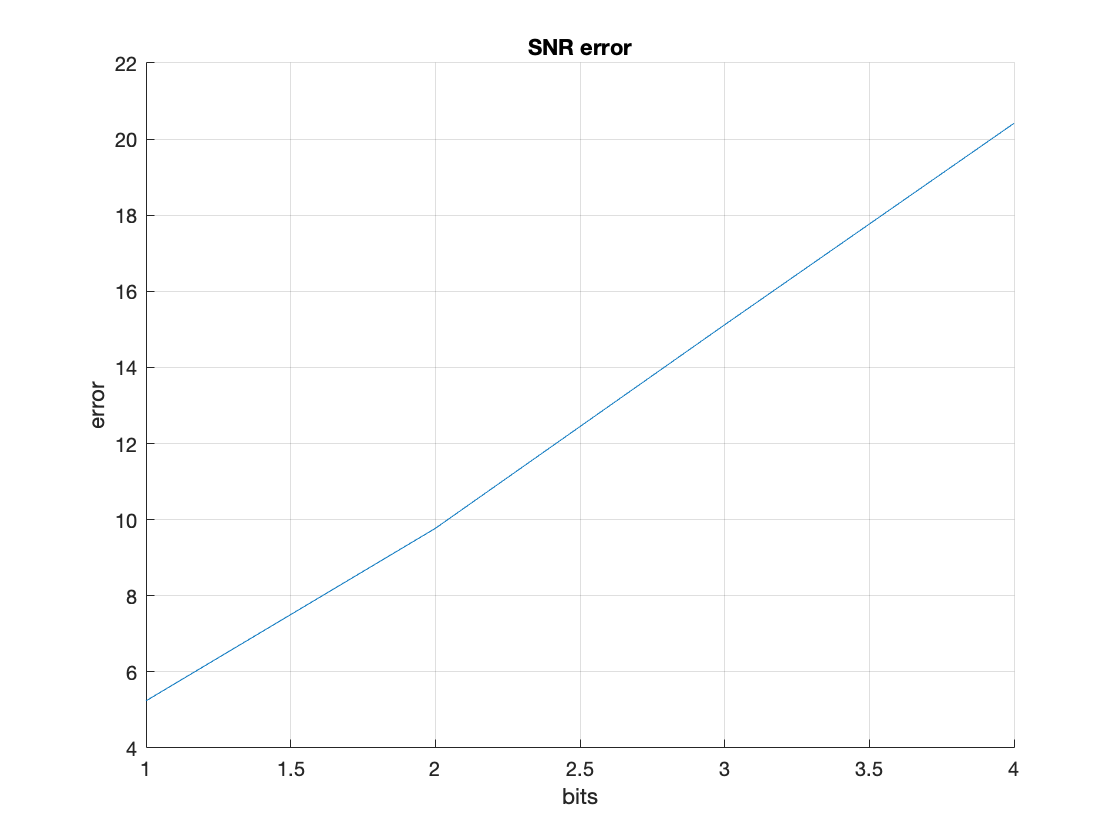

error_SNR_norm =     5.2393    9.7720   15.1220   20.4157



figure(18)
error_SNR_norm = QuantizationErrorSNR(normal_signal, quantorization_signal_norm, x_min, x_max)

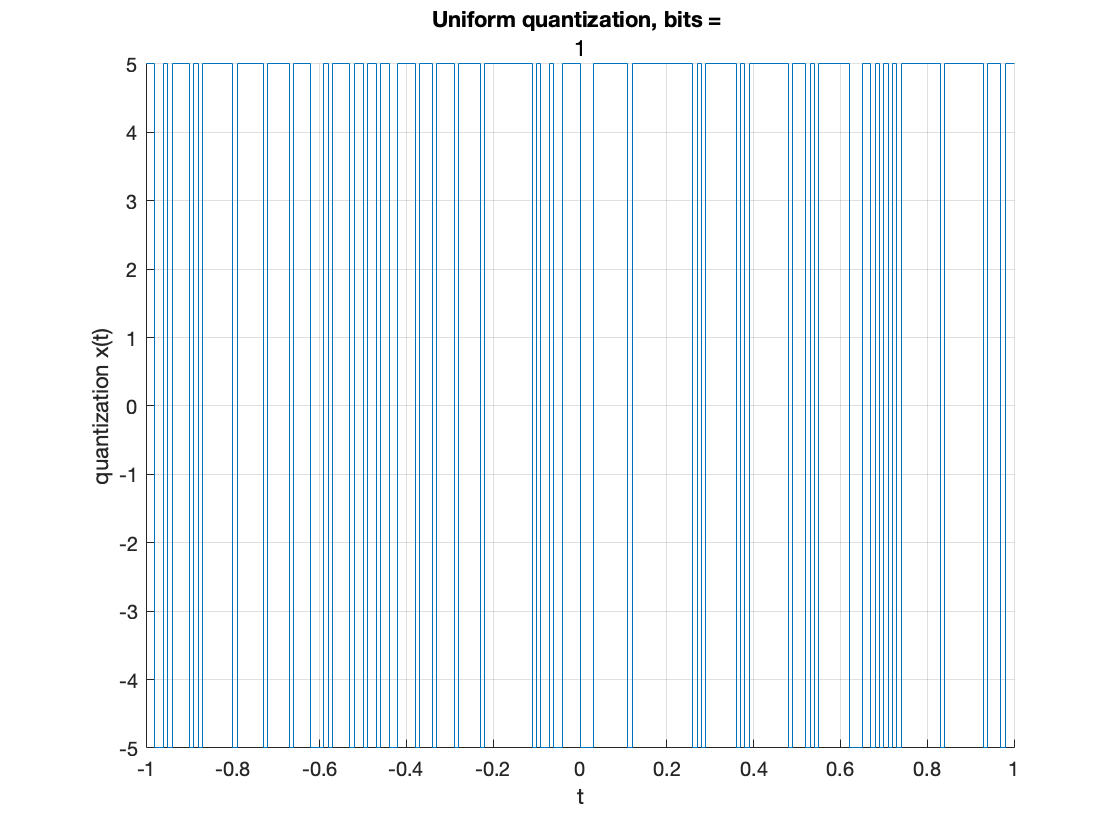

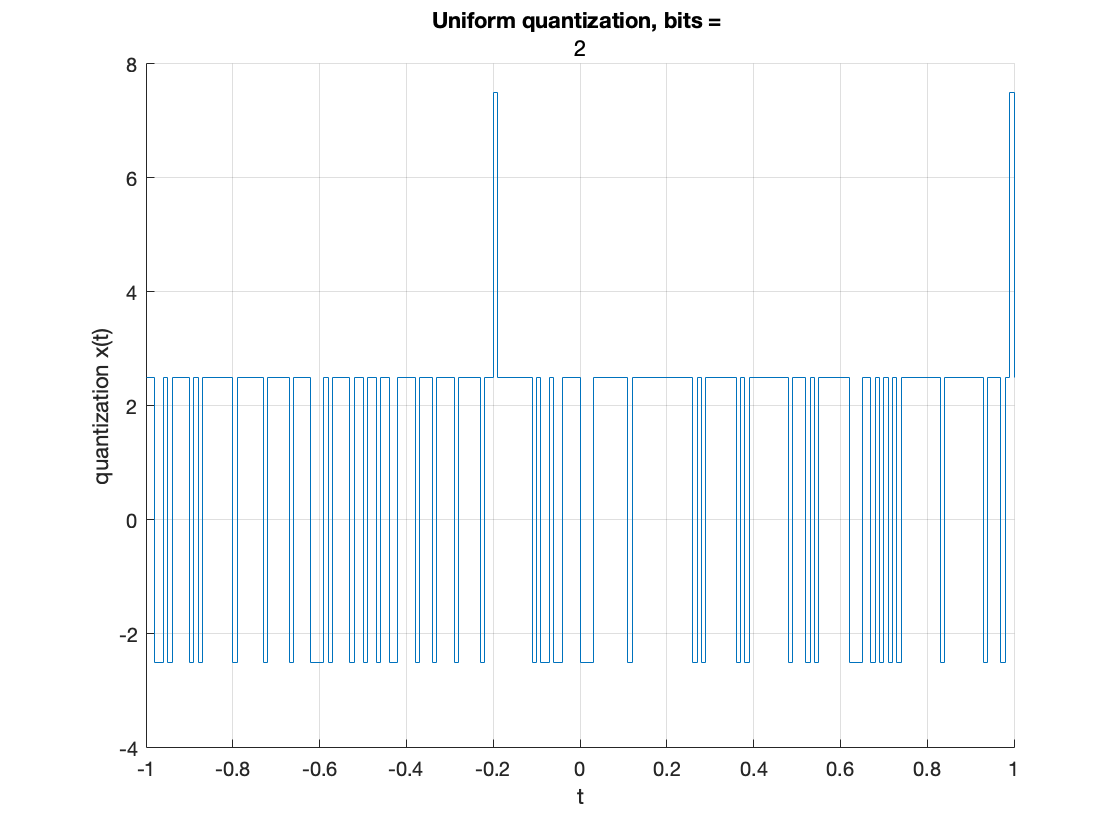

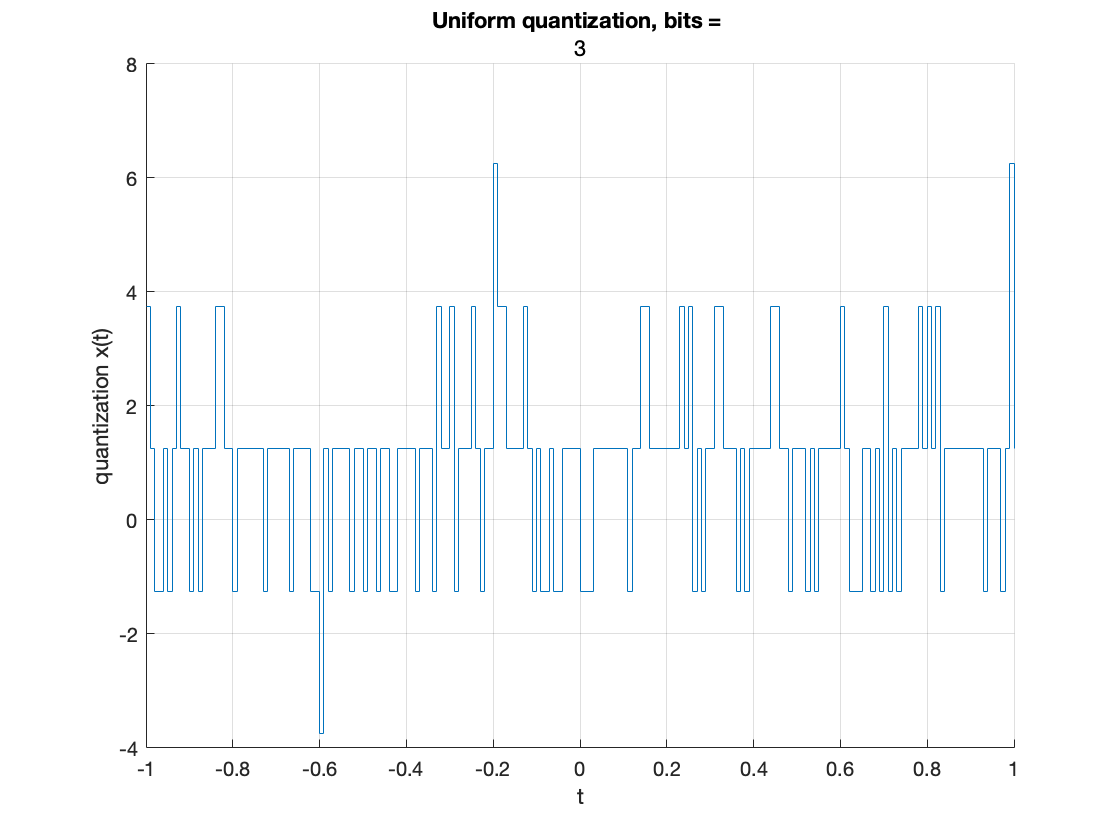

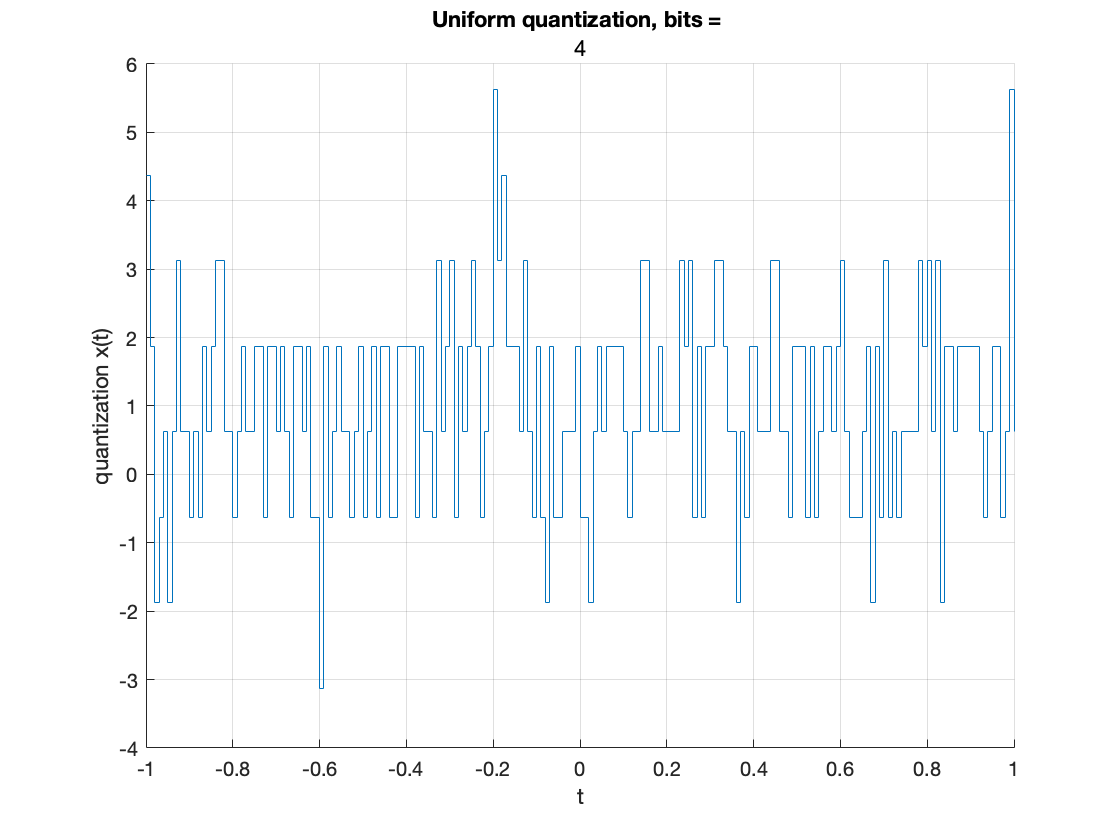


%TASK-2-PART-9-----------------------------------------
quantorization_signal_un = zeros(4,length(original_signal));
for k = 1:1:4
    figure(18+k)
    quantorization_signal_un(k,:) = UniformQuantization(normal_signal, count_set, k, x_min, x_max);
end

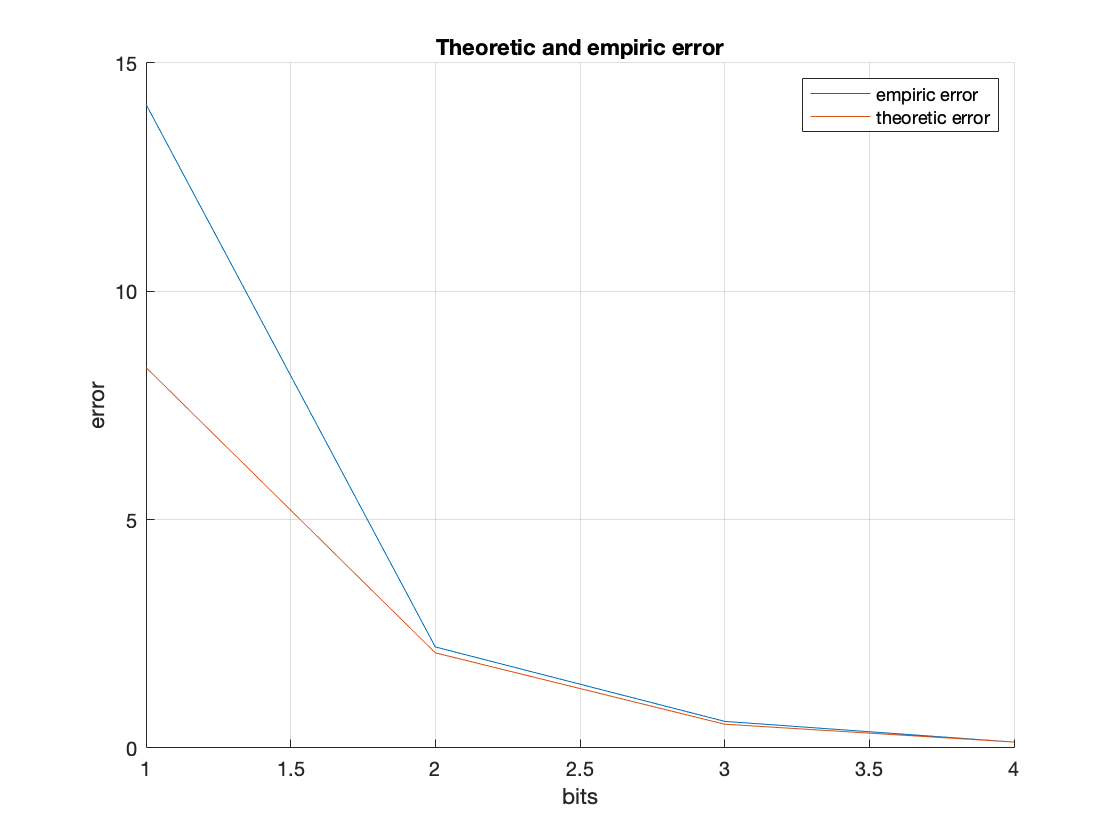

error_empiric_un =    14.0970    2.2125    0.5828    0.1300


error_theoretic_un =     8.3333    2.0833    0.5208    0.1302


figure(23)
[error_empiric_un, error_theoretic_un] = QuantizationError(normal_signal, quantorization_signal_un, x_min, x_max)

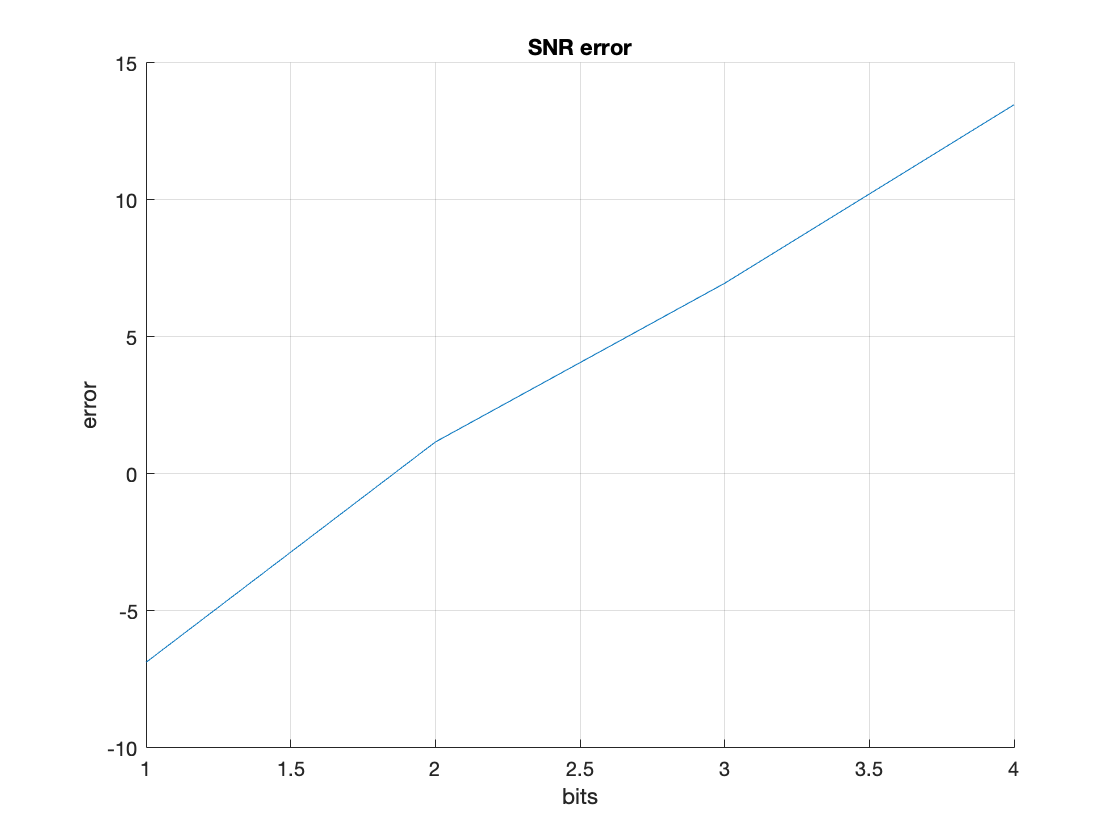

error_SNR_un =    -6.8748    1.1677    6.9615   13.4765



figure(24)
error_SNR_un = QuantizationErrorSNR(normal_signal, quantorization_signal_un, x_min, x_max)

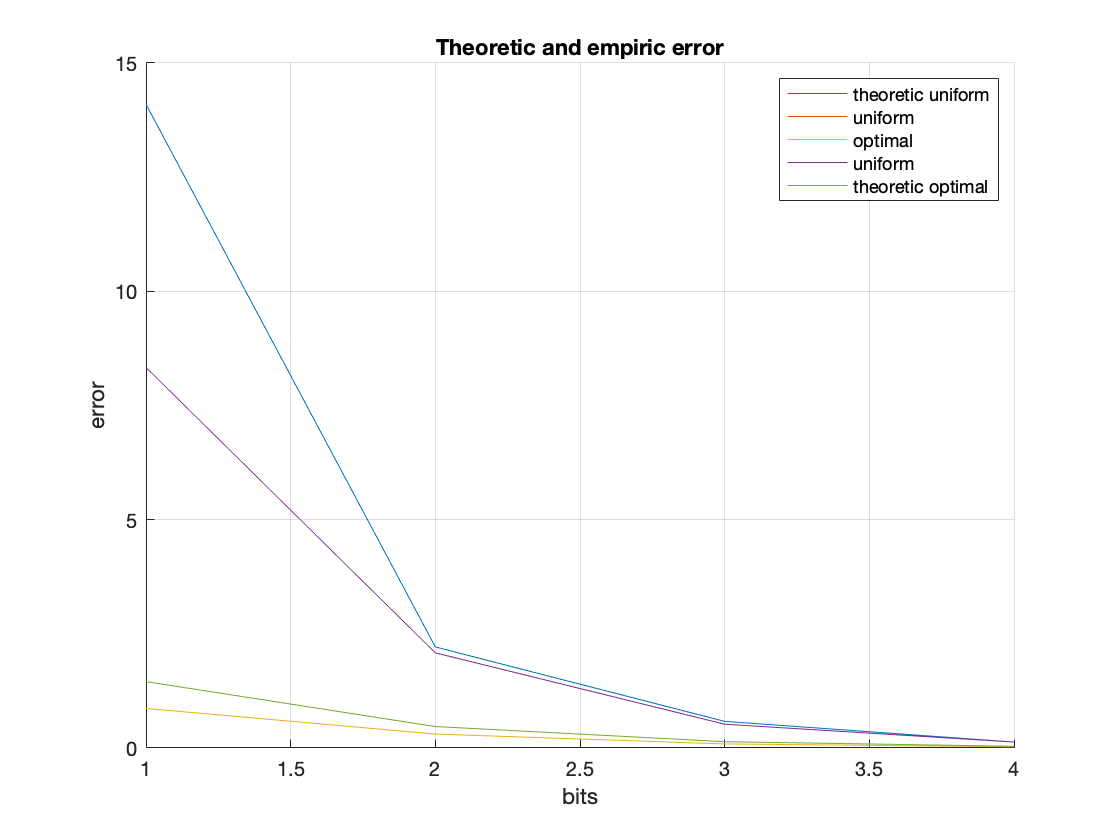


%COMMENT-2---------------------------------------------
figure(25)
hold on; grid on;
e(1) = error_teor(t1_new,d1_new,sigma,m);
e(2) = error_teor(t2_new,d2_new,sigma,m);
e(3) = error_teor(t3_new,d3_new,sigma,m);
e(4) = error_teor(t4_new,d4_new,sigma,m);
QuantizationError(normal_signal, quantorization_signal_un, x_min, x_max);
QuantizationError(normal_signal, quantorization_signal_norm, x_min, x_max);
plot([1:4],e);
legend('theoretic uniform','uniform', 'optimal','uniform', 'theoretic optimal')